# Problema de Despacho Econômico para 19 Geradores

## Parâmetros do algoritmo

clear,clc
tic
n = 100; % Número de morcegos
MaxIterations = 1000; % Número máximo de iterações
A0 = 1; % Loudness inicial
r0 = 0.5; % Pulse rate inicial
alpha = 0.9; % Taxa de redução de loudness (valor recomendado pela literatura)
gamma = 0.9; % Taxa de aumento de pulse rate (valor recomendado pela literatura)
betta = -1 + 2*rand(1); % vetor aleatório pertence ao intervalo [0,1]
f_min = zeros(n, 1); % Frequência mínima
f_max = rand(n, 1);% Frequência máxima
% sigma = 1; % fator de escala
% f_max = transpose(linspace(1000*n, 1)); % Frequência máxima
% f_max = 100000.*rand(n,1);

## Parâmetros do Sistema de Geração Termelétrico

% Constantes
G = [1     2     3     4     5     6     7     8     9    10    11    12    13   14   15   16   17   18   19]; % 19 unidades de geração
Pmin_G = [100   120   100     8    50   150    50   100   200    15    50    25    50     0    20    15    15    50   400]; % Potência gerada mínima de cada unidade
Pmax_G = [300.0000  438.0000  250.0000   25.0000   63.7500  300.0000   63.7500  500.0000  600.0000   40.0000  150.0000   75.0000   63.7500   95.0000  220.0000   80.0000   80.0000  230.0000  500.0000]; % Potência gerada máxima de cada unidade
PD = 2908; % Potência ativa demandada pelo sistema [MW]

% Parâmetros da função de custo de produção das unidades termelétricas
a = [0.0097    0.0055    0.0055    0.0025         0    0.0080         0    0.0075    0.0085    0.0090    0.0045    0.0025   0    0.0045    0.0065    0.0045    0.0025    0.0045    0.0080];
b = [6.8000    4.0000    4.0000    0.8500    5.2800    3.5000    5.4390    6.0000    6.0000    5.2000    1.6000    0.8500   2.5500    1.6000    4.7000    1.4000    0.8500    1.6000    5.5000];
c = [119.0000   90.0000   45.0000         0    0.8910  110.0000   21.0000   88.0000   55.0000   90.0000   65.0000   78.0000   49.0000   85.0000   80.0000   90.0000   10.0000   25.0000   90.0000];
e = [ 90    79     0     0     0     0     0    50     0     0     0    58     0     0    92     0     0     0     0];
f = [0.7200    0.0500         0         0         0         0         0    0.5200         0         0         0    0.0200   0         0    0.7500         0         0         0         0];

## Função objetivo

% Custo de produção da unidade de geração termelétrica
cost_function = @(PG) sum(a .* PG.^2 + b .* PG + c + abs(e .* sin(f .* (Pmin_G - PG))));

obj_fun = @(PG) cost_function(PG) + 1e6 * abs(sum(PG) - PD); % função objetivo com penalização

## Função inicialização da população de morcegos

% Inicialização da população de morcegos
d = length(G); % Dimensão do problema
LB = Pmin_G; % Limite inferior
UB = Pmax_G; % Limite superior
x = LB + (UB - LB) .* rand(n, d); % Posições iniciais
v = zeros(n, d); % Velocidades iniciais
freq = zeros(n, 1); % Frequências iniciais
pulse_rate = r0 * ones(n, 1); % Pulse rates
loudness = A0 * ones(n, 1); % Loudness
fitness = zeros(n, 1);

## Função principal

% Avaliar a população inicial
for i = 1:n
    fitness(i) = obj_fun(x(i, :));
end

% Encontrar a melhor solução inicial
[best_fitness, best_idx] = min(fitness);
x_best = x(best_idx, :);


% Loop principal do algoritmo
t = 1;
while t <= MaxIterations
    for i = 1:n
        % Atualizar frequência
        freq(i) = f_min(i, :) + (f_max(i, :) - f_min(i, :)).*betta;

        % Atualizar velocidade
        v(i, :) = v(i, :) + (x(i, :) - x_best) * freq(i);

        % Atualizar posição
        x(i, :) = x(i, :) + v(i, :);

        % Limitar posição aos limites inferiores e superiores
        x(i, :) = max(LB, min(UB, x(i, :)));

        % Selecionar uma solução entre as melhores soluções
        if rand > pulse_rate(i)
            epsilon = randn(size(x_best)); % vetor aleatório extraído de uma distribuição  normal Gaussiana N(0,1)
            x_new = x_best + epsilon .* mean(loudness);
        else
            x_new = LB + (UB - LB) .* rand(1, d);
        end

        % Limitar nova posição aos limites inferiores e superiores
        x_new = max(LB, min(UB, x_new));

        % Ajustar x_new para atender à restrição de igualdade (sum(PG) = PD)
        sum_x_new = sum(x_new);
        if sum_x_new ~= PD
            x_new = x_new * (PD / sum_x_new);
            % Garantir que ainda esteja dentro dos limites após o ajuste
            x_new = max(LB, min(UB, x_new));
        end

        % Avaliar nova solução
        f_new = obj_fun(x_new);

        % Verificar condição de aceitação
        if rand < loudness(i) && f_new < fitness(i)
            x(i, :) = x_new;
            fitness(i) = f_new;
            loudness(i) = alpha * loudness(i);
            pulse_rate(i) = r0 * (1 - exp(-gamma * t));
        end

        % Atualizar a melhor solução
        if f_new < best_fitness
            x_best = x_new;
            best_fitness = f_new;
        end
    end
    t = t + 1;
end

## Resultado Final

format long

disp('Potência gerada por cada unidade de geração:');

Potência gerada por cada unidade de geração:


for k = 1:length(G)
    fprintf('Unidade %d: %.5f MW\n', G(k), x_best(k));
end

Unidade 1: 239.61715 MW
Unidade 2: 366.74336 MW
Unidade 3: 230.87125 MW
Unidade 4: 24.99307 MW
Unidade 5: 62.30449 MW
Unidade 6: 237.16368 MW
Unidade 7: 57.77841 MW
Unidade 8: 142.25668 MW
Unidade 9: 225.41586 MW
Unidade 10: 39.73693 MW
Unidade 11: 149.83915 MW
Unidade 12: 74.96975 MW
Unidade 13: 63.66200 MW
Unidade 14: 94.97365 MW
Unidade 15: 107.98570 MW
Unidade 16: 79.95714 MW
Unidade 17: 79.91430 MW
Unidade 18: 229.76741 MW
Unidade 19: 400.05001 MW


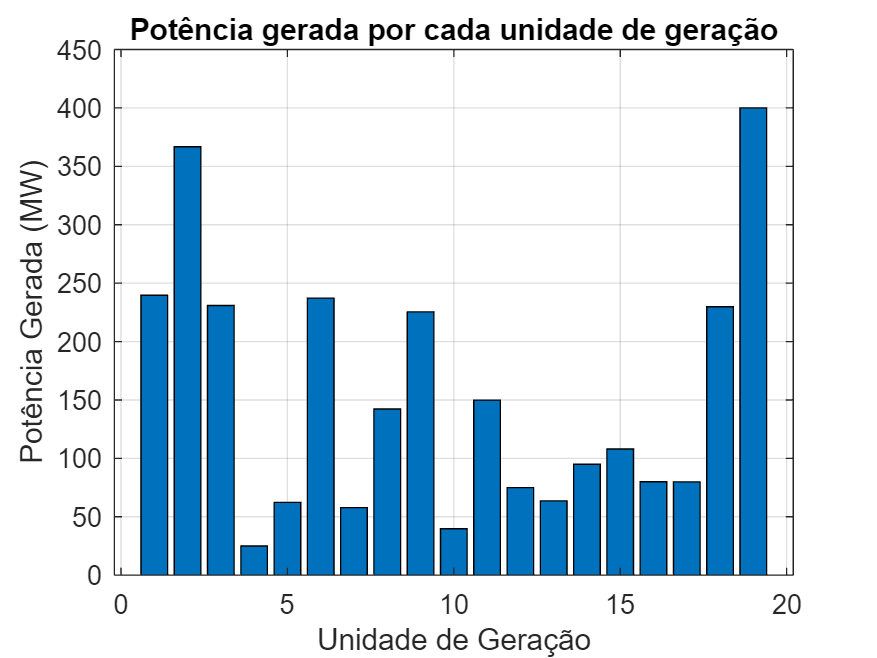


% Gráfico de barras
bar(G, x_best);
xlabel('Unidade de Geração');
ylabel('Potência Gerada (MW)');
title('Potência gerada por cada unidade de geração');
grid on;


total_power_generated = sum(x_best);
fprintf('Potência total gerada: %.5f MW\n', total_power_generated);

Potência total gerada: 2908.00000 MW


fprintf('Custo da produção ($): %.5f ', best_fitness);

Custo da produção ($): 17494.06342 

disp('Melhor solução encontrada:');

Melhor solução encontrada:


disp(x_best);

   1.0e+02 *

   2.396171534308937   3.667433616191973   2.308712453336470   0.249930655244889   0.623044914619112   2.371636785862192   0.577784125990567   1.422566817012248   2.254158591237753   0.397369289678864   1.498391534509682   0.749697535946913   0.636620034774581   0.949736489930578   1.079856989971347   0.799571417696084   0.799142969491600   2.297674145609847   4.000500098586360



toc

Elapsed time is 48.920332 seconds.


### Função de custo de produção da unidade de geração termelétrica

function C = unit_cost(PG_k, a_k, b_k, c_k, e_k, f_k, Pmin_G_k)
    C = a_k * PG_k^2 + b_k * PG_k + c_k + abs(e_k * sin(f_k * (Pmin_G_k - PG_k)));
end
